B

Forma de Serie Exponencial Compleja:

N = 20; % Número de coeficientes
T = 4; % Período

% Cálculo de coeficientes
ck = zeros(1, 2*N+1);

t = linspace(-2, 2, 1000); % Dominio de tiempo para la gráfica
x = @(t) t - t.^3; % Definición de la señal

for k = -N:N
    ck(k+N+1) = 1/T * integral(@(t) (t - t.^3) .* exp(-1i*2*pi*k*t/T), -T/2, T/2);
end

% Escribe los valores de los coeficientes en el informe
fprintf('Valores de los coeficientes de la Serie Exponencial Compleja:\n');

Valores de los coeficientes de la Serie Exponencial Compleja:


for k = -N:N
    fprintf('c_%d = %f\n', k, ck(k+N+1));
end

c_-20 = 0.000000
c_-19 = -0.000000
c_-18 = -0.000000
c_-17 = 0.000000
c_-16 = -0.000000
c_-15 = 0.000000
c_-14 = -0.000000
c_-13 = 0.000000
c_-12 = -0.000000
c_-11 = -0.000000
c_-10 = 0.000000
c_-9 = 0.000000
c_-8 = -0.000000
c_-7 = 0.000000
c_-6 = -0.000000
c_-5 = 0.000000
c_-4 = -0.000000
c_-3 = 0.000000
c_-2 = -0.000000
c_-1 = 0.000000
c_0 = 0.000000
c_1 = 0.000000
c_2 = -0.000000
c_3 = 0.000000
c_4 = -0.000000
c_5 = 0.000000
c_6 = -0.000000
c_7 = 0.000000
c_8 = -0.000000
c_9 = 0.000000
c_10 = 0.000000
c_11 = -0.000000
c_12 = -0.000000
c_13 = 0.000000
c_14 = -0.000000
c_15 = 0.000000
c_16 = -0.000000
c_17 = 0.000000
c_18 = -0.000000
c_19 = -0.000000
c_20 = 0.000000


Forma de Serie Trigonométrica:

N = 20; % Número de coeficientes
T = 4; % Período

% Cálculo de coeficientes
ak = zeros(1, N+1);
bk = zeros(1, N+1);

t = linspace(-2, 2, 1000); % Dominio de tiempo para la gráfica
x = @(t) t - t.^3; % Definición de la señal

for k = 0:N
    ak(k+1) = (2/T) * integral(@(t) (t - t.^3) .* cos(2*pi*k*t/T), -T/2, T/2);
    bk(k+1) = (2/T) * integral(@(t) (t - t.^3) .* sin(2*pi*k*t/T), -T/2, T/2);
end

% Escribe los valores de los coeficientes en el informe
fprintf('Valores de los coeficientes de la Serie Trigonométrica:\n');

Valores de los coeficientes de la Serie Trigonométrica:


for k = 0:N
    fprintf('a_%d = %f\n', k, ak(k+1));
    fprintf('b_%d = %f\n', k, bk(k+1));
end

a_0 = 0.000000


b_0 = 0.000000


a_1 = 0.000000


b_1 = -0.723571


a_2 = -0.000000


b_2 = 1.522841


a_3 = 0.000000


b_3 = -1.158567


a_4 = -0.000000


b_4 = 0.906552


a_5 = 0.000000


b_5 = -0.739175


a_6 = 0.000000


b_6 = 0.622286


a_7 = -0.000000


b_7 = -0.536647


a_8 = 0.000000


b_8 = 0.471418


a_9 = -0.000000


b_9 = -0.420166


a_10 = 0.000000


b_10 = 0.378876


a_11 = -0.000000


b_11 = -0.344921


a_12 = -0.000000


b_12 = 0.316518


a_13 = 0.000000


b_13 = -0.292415


a_14 = -0.000000


b_14 = 0.271709


a_15 = -0.000000


b_15 = -0.253731


a_16 = 0.000000


b_16 = 0.237977


a_17 = -0.000000


b_17 = -0.224059


a_18 = 0.000000


b_18 = 0.211676


a_19 = 0.000000


b_19 = -0.200586


a_20 = -0.000000


b_20 = 0.190599


C

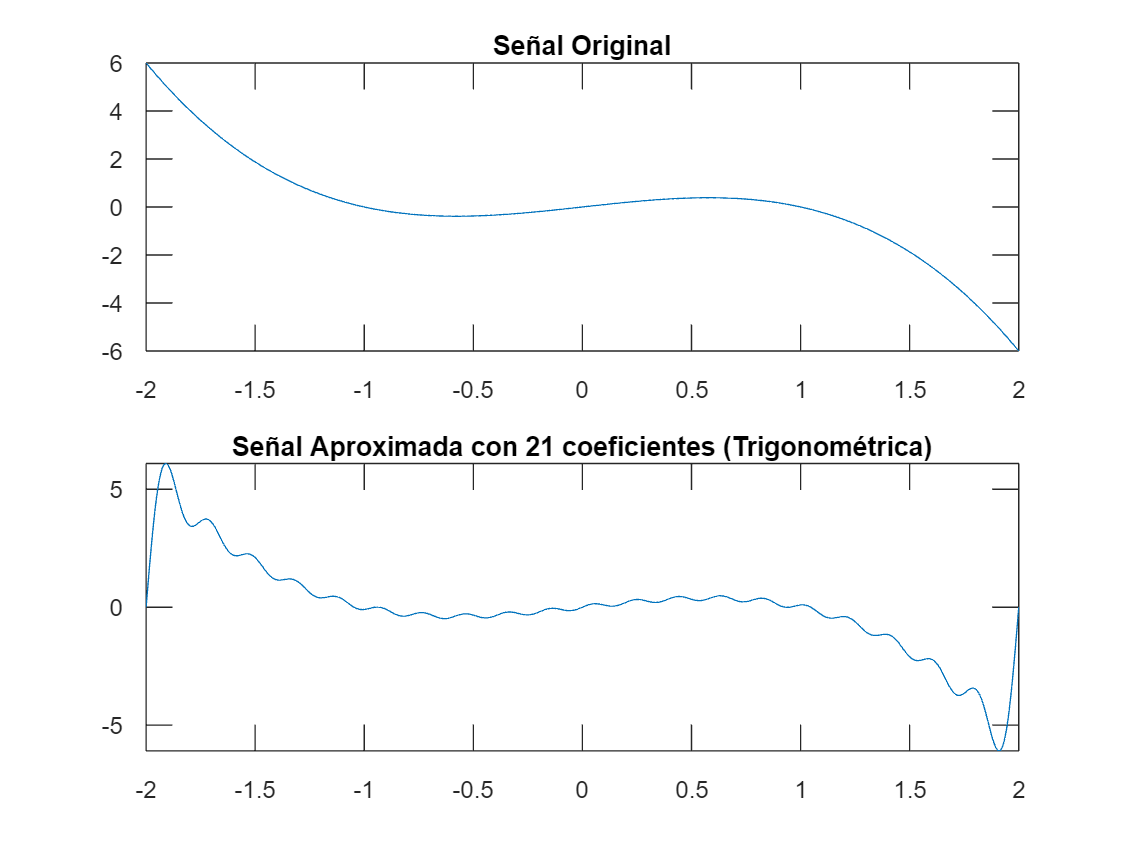

% Solicitar al usuario el número de coeficientes N
N = input('Ingrese el número de coeficientes N: ');

% Verificar si el usuario desea Serie Exponencial Compleja o Serie Trigonométrica
serie_type = input('Elija el tipo de serie (Exponencial o Trigonométrica): ', 's');

T = 4; % Período
t = linspace(-2, 2, 1000); % Dominio de tiempo para la gráfica
x = @(t) t - t.^3; % Definición de la señal

if strcmpi(serie_type, 'Exponencial')
    % Cálculo de coeficientes Serie Exponencial Compleja
    ck = zeros(1, 2*N+1);
    for k = -N:N
        ck(k+N+1) = 1/T * integral(@(t) (t - t.^3) .* exp(-1i*2*pi*k*t/T), -T/2, T/2);
    end

    % Cálculo de la señal aproximada por Serie Exponencial Compleja
    x_approx = zeros(size(t));
    for k = -N:N
        x_approx = x_approx + ck(k+N+1) * exp(1i*2*pi*k*t/T);
    end

    % Gráficos
    figure;
    subplot(2, 1, 1);
    plot(t, x(t));
    title('Señal Original');
    subplot(2, 1, 2);
    plot(t, real(x_approx), 'r', t, imag(x_approx), 'b');
    title(['Señal Aproximada con ', num2str(2*N+1), ' coeficientes (Exponencial)']);
    legend('Parte Real', 'Parte Imaginaria');
else
    % Cálculo de coeficientes Serie Trigonométrica
    ak = zeros(1, N+1);
    bk = zeros(1, N+1);
    
    for k = 0:N
        ak(k+1) = (2/T) * integral(@(t) (t - t.^3) .* cos(2*pi*k*t/T), -T/2, T/2);
        bk(k+1) = (2/T) * integral(@(t) (t - t.^3) .* sin(2*pi*k*t/T), -T/2, T/2);
    end

    % Cálculo de la señal aproximada por Serie Trigonométrica
    x_approx = zeros(size(t));
    for k = 0:N
        x_approx = x_approx + ak(k+1) * cos(2*pi*k*t/T) + bk(k+1) * sin(2*pi*k*t/T);
    end

    % Gráficos
    figure;
    subplot(2, 1, 1);
    plot(t, x(t));
    title('Señal Original');
    subplot(2, 1, 2);
    plot(t, x_approx);
    title(['Señal Aproximada con ', num2str(N+1), ' coeficientes (Trigonométrica)']);
end

D.

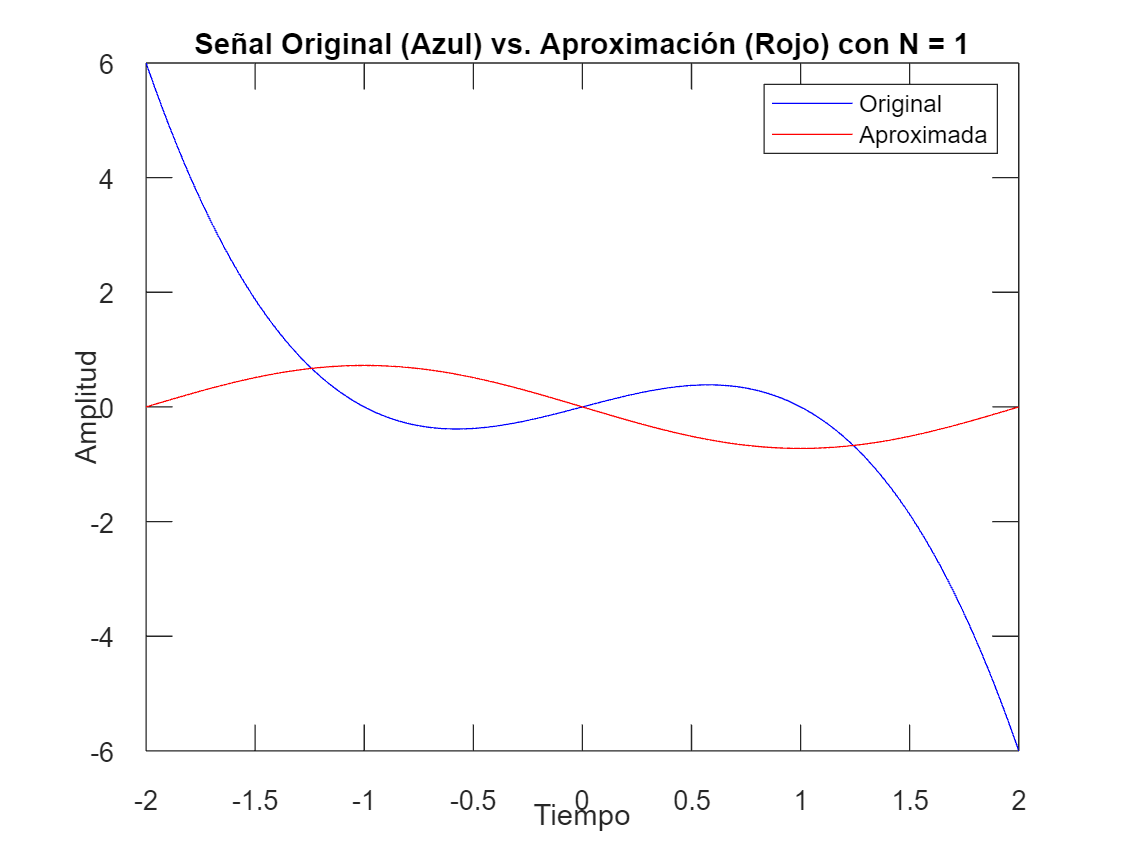

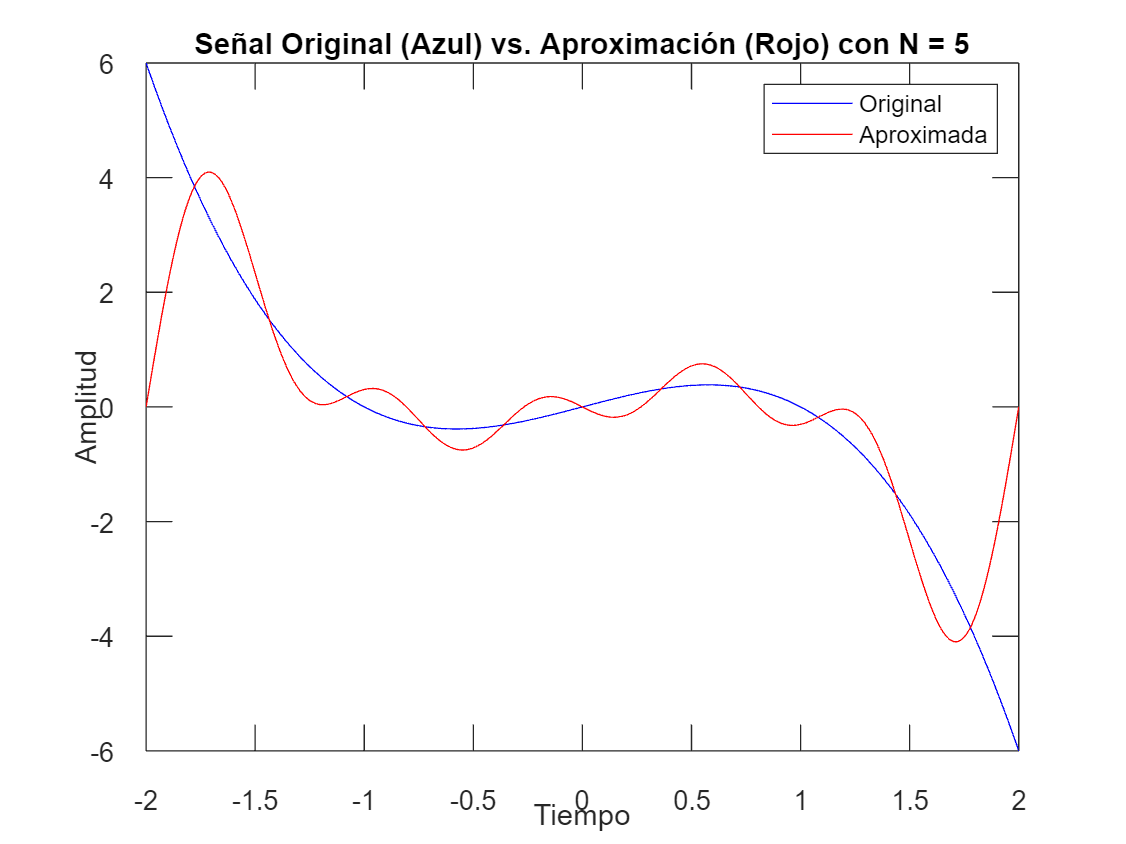

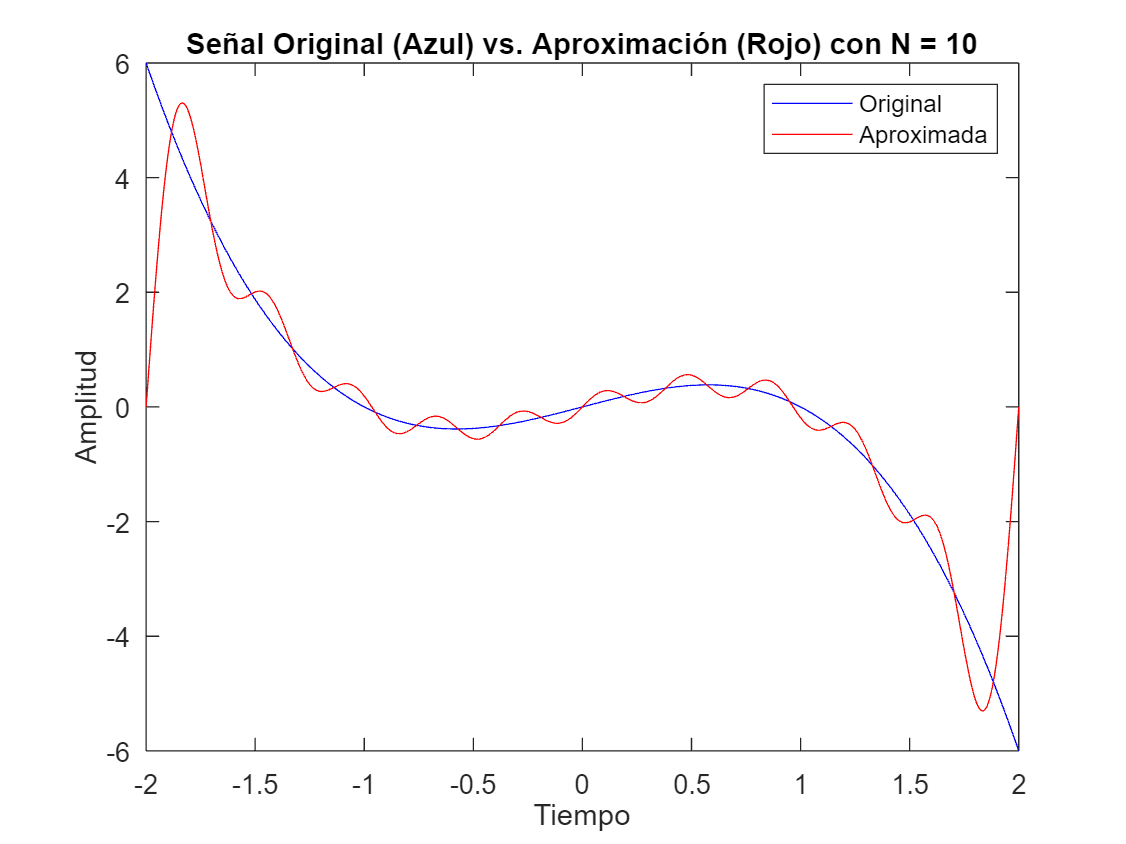

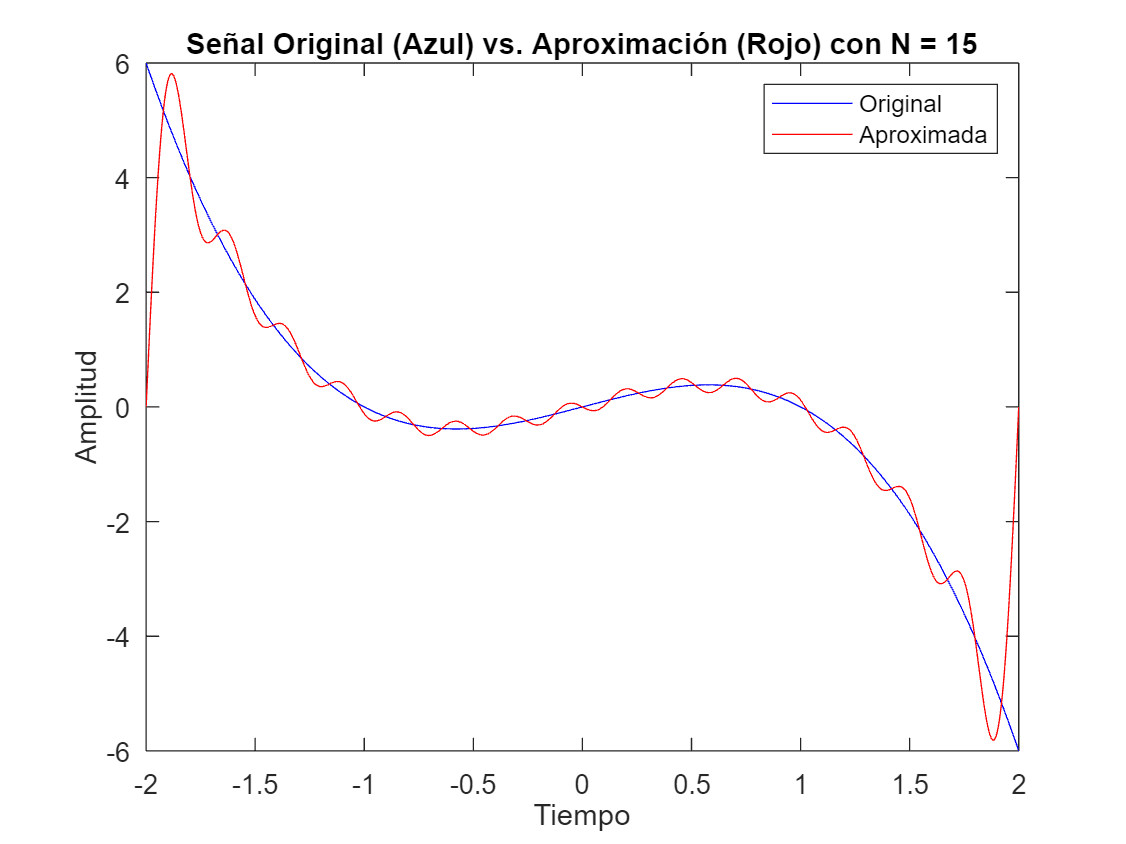

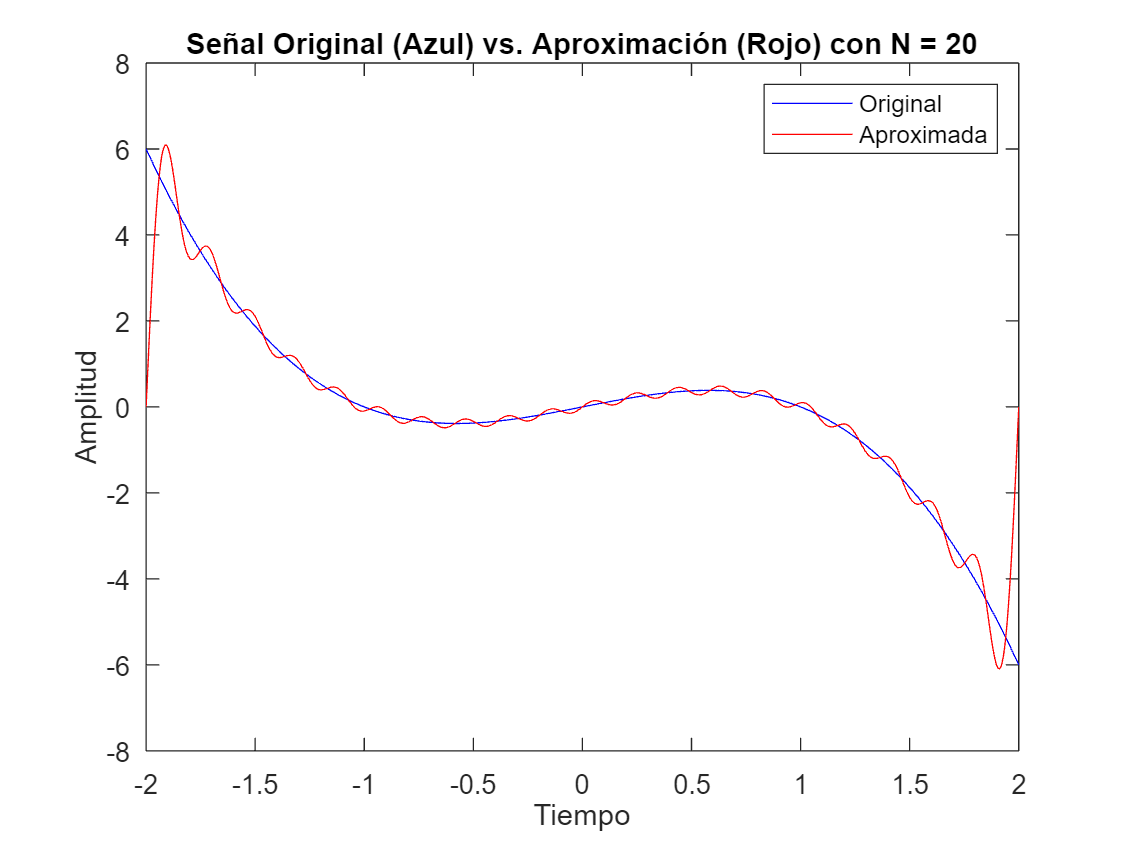

T = 4; % Período
t = linspace(-2, 2, 1000); % Dominio de tiempo para la gráfica
x = @(t) t - t.^3; % Definición de la señal

N_values = [1, 5, 10, 15, 20];

for N = N_values
    % Cálculo de coeficientes Serie Trigonométrica
    ak = zeros(1, N+1);
    bk = zeros(1, N+1);

    for k = 0:N
        ak(k+1) = (2/T) * integral(@(t) (t - t.^3) .* cos(2*pi*k*t/T), -T/2, T/2);
        bk(k+1) = (2/T) * integral(@(t) (t - t.^3) .* sin(2*pi*k*t/T), -T/2, T/2);
    end

    % Cálculo de la señal aproximada por Serie Trigonométrica
    x_approx = zeros(size(t));
    for k = 0:N
        x_approx = x_approx + ak(k+1) * cos(2*pi*k*t/T) + bk(k+1) * sin(2*pi*k*t/T);
    end

    % Gráficos
    figure;
    plot(t, x(t), 'b', t, x_approx, 'r');
    title(['Señal Original (Azul) vs. Aproximación (Rojo) con N = ' num2str(N)]);
    xlabel('Tiempo');
    ylabel('Amplitud');
    legend('Original', 'Aproximada');
end

E

T = 4; % Período
t = linspace(-2, 2, 1000); % Dominio de tiempo para la gráfica
x = @(t) t - t.^3; % Definición de la señal

N_values = [1, 5, 10, 15, 20];
P_original = 1/T * integral(@(t) (x(t).^2), -T/2, T/2); % Potencia promedio de la señal original

for N = N_values
    % Cálculo de coeficientes Serie Trigonométrica
    ak = zeros(1, N+1);
    bk = zeros(1, N+1);

    for k = 0:N
        ak(k+1) = (2/T) * integral(@(t) (t - t.^3) .* cos(2*pi*k*t/T), -T/2, T/2);
        bk(k+1) = (2/T) * integral(@(t) (t - t.^3) .* sin(2*pi*k*t/T), -T/2, T/2);
    end

    % Cálculo de la potencia promedio de la señal aproximada
    P_approx = 0.5 * sum(ak.^2 + bk.^2); % Teorema de Parseval

    % Imprimir los resultados
    fprintf('N = %d:\n', N);
    fprintf('Potencia promedio de la señal original: %f\n', P_original);
    fprintf('Potencia promedio de la señal aproximada: %f\n', P_approx);
    fprintf('\n');
end

N = 1:


Potencia promedio de la señal original: 4.076190


Potencia promedio de la señal aproximada: 0.261778


N = 5:


Potencia promedio de la señal original: 4.076190


Potencia promedio de la señal aproximada: 2.776547


N = 10:


Potencia promedio de la señal original: 4.076190


Potencia promedio de la señal aproximada: 3.385323


N = 15:


Potencia promedio de la señal original: 4.076190


Potencia promedio de la señal aproximada: 3.606756


N = 20:


Potencia promedio de la señal original: 4.076190


Potencia promedio de la señal aproximada: 3.720858
